## **Session Data**

### **KingKong.01898**

- Premininary data collecting on 02/05/2020, **with perturbation**

- Targets (m): [0, 0.10], [0 0.05]

- Force Threshold (N): 10, 20

- Comment: extremely hard on short direction with high force threshold, failure a lot of trials. 

% read the session
ss1898 = SessionScan(1898);

Loading raw FT and WAM...
FT High Sample...
WAM High Sample...
Trialfy...
Not enough long in trial1
  05%...  10%...  15%...  20%...  25%...  30%...  35%...  40%...  45%...  50%...  55%...  60%...  65%...  70%...  75%...  80%...  85%...  90%...  95%...  100%...  100%  FINISHED!


% trial count on each combo
taskScanTrials(ss1898);

FT: 10N, Dist: 0.05m, trials: 30 / 34
FT: 10N, Dist: 0.10m, trials: 29 / 30
FT: 20N, Dist: 0.05m, trials: 30 / 144
FT: 20N, Dist: 0.10m, trials: 30 / 44


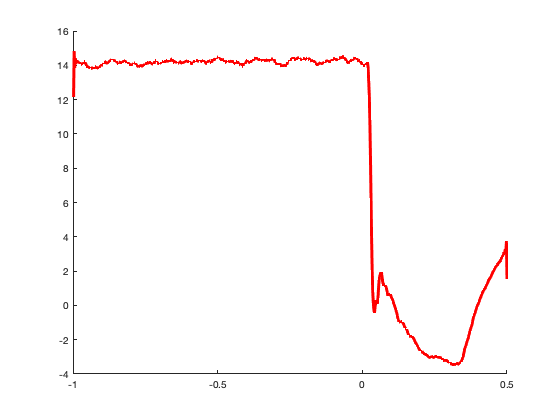

Undefined function or variable 'jbfill'.

Error in SessionScan/plotMeantrialForce (line 814)
                    [axhf, msg] = jbfill(resample_t, force_up, force_dn, obj.col_vec(col_i,:), obj.col_vec(col_i,:), 1, 0.3);

% figures of mean trial
axhf = plotMeantrialForce(ss1898);

axhp = plotMeantrialPos(ss1898);
axhv = plotMeantrialVel(ss1898);

### **KingKong.01910**

- Preliminary data collecting on 02/09/2020, no perturbation

- Targets (m): [0, 0.10], [0 0.05]

- Force Threshold (N): 10, 20

- Comment: extremely hard on short direction with high force threshold, failure a lot of trials. 

% read the session
ss1910 = SessionScan(1910);
% trial count on each combo
taskScanTrials(ss1910);
% figures of mean trial
axhf = plotMeantrialForce(ss1910);
axhp = plotMeantrialPos(ss1910);
axhv = plotMeantrialVel(ss1910);

### **KingKong.01912**

- Preliminary data collecting on 02/09/2020, no perturbation

- Targets (m): [0, 0.10], [0 0.05]

- Force Threshold (N): 10, 20

- Comment: Much easier whey I sit down, arm curved 30cm before right sholder 

% read the session
ssnum = 1912;

% read data
fObjectName = ['ss' num2str(ssnum)];
if exist(fObjectName,'var')==0
    eval([fObjectName '= SessionScan(' num2str(ssnum) ');']);
end

% trial count on each combo
taskScanTrials(ss1912);
% figures of mean trial
axhf = plotMeantrialForce(ss1912);
axhp = plotMeantrialPos(ss1912);
axhv = plotMeantrialVel(ss1912);

% read the session
ssnum = 1913;

% read data
fObjectName = ['ss' num2str(ssnum)];
if exist(fObjectName,'var')==0
    eval([fObjectName '= SessionScan(' num2str(ssnum) ');']);
end
% trial count on each combo
taskScanTrials(ss1913);
% figures of mean trial
axhf = plotMeantrialForce(ss1913);
axhp = plotMeantrialPos(ss1913);
axhv = plotMeantrialVel(ss1913);
axhp = ss1913.trials(18).plotPredictedForceOnPosition()

## Sanity Check certain session:

Sanity check should include: 

- Trial finish condition (color label each trial sucess/failure);   - Just see how the subject works on trials;

- Force baseline plot. - See if force baseline has changed significantly during trials. If exist, means force measurement are erroneous; 

- Original task curves on specific task. - To check each trial and the trial variance. (Q: how to see each trial according to their line?)

% specify session
ssnum = 1898;
% read data
fObjectName = ['ss' num2str(ssnum)];
if exist(fObjectName,'var')==0
    eval([fObjectName '= SessionScan(' num2str(ssnum) ');']);
end
% 1. Trial Finish Condition
axh = eval(fObjectName).plotTaskTrialFinish()
% 2. Force Baseline Plot

% 3. Original Curve on each trial

## Generate only-perturbation files:

For purpose of Impedance estimation using perturbation method, generate a easy analysis file.  

In current task setting, the perturbation applies at only task state 3: **ForceRamp**. Thus, in current code, we only select force ramp state [1]. After the time selection, we choose certain trials we interested [2], during where wam member function was called [3] and generate data / seperate file. 

`[1] function ``TrialScan``      obj = findPerterbTime(obj, sessionScanObj)        `

`    % find corresponding time in each trial`

`[2] function ``SessionScan``    obj = generateWamPertData(obj)                    `

`    % select trials based on conditions, and call [3]`

`[3] function ``SessionScanWam`` obj = concatinateTrials2File(obj, tarL_list, fTh_list, rdt_ranges) `

`    % based on rdt (ReadTime label), select data and save in (``SessionScan``) obj.wam.Data_pert, or a seperate file (see code)`

`Notice: ``In the saved file, the data sequene might be different from our old condition. See:`

          `SessionScanWam ``SessionScanWam(ss_num) for more defination`

% specify session
ss1926 = SessionScan(1926);     % during this part already do [1]

Loading raw FT and WAM...


% connect data
ss1926.generateWamPertData();   %                          do [2]
axhp = plotMeantrialPos(ss1926);
% Make plots
get_Z_spectral(ss1926.wam.Data_pert(1,:));
get_Z_spectral(ss1926.wam.Data_pert(2,:));
get_Z_spectral(ss1926.wam.Data_pert(3,:));
get_Z_spectral(ss1926.wam.Data_pert(4,:));

legend({['T_x: ',num2str(ss1926.wam.Data_pert(1,1).x0*100),'cm, T_f: ',num2str(ss1926.wam.Data_pert(1,1).FT),'N'],...
        ['T_x: ',num2str(ss1926.wam.Data_pert(2,1).x0*100),'cm, T_f: ',num2str(ss1926.wam.Data_pert(2,1).FT),'N'],...
        ['T_x: ',num2str(ss1926.wam.Data_pert(3,1).x0*100),'cm, T_f: ',num2str(ss1926.wam.Data_pert(3,1).FT),'N'],...
        ['T_x: ',num2str(ss1926.wam.Data_pert(4,1).x0*100),'cm, T_f: ',num2str(ss1926.wam.Data_pert(4,1).FT),'N']});
                    
delta_x=[(15/1000)*100,...
(21/1000)*100,...
(30/1000)*100,...
(32/1000)*100]

## Impedance estimation using Scott's method

Impedance estimate using F = K(x-x0) - Dx` - Ax`` - Jx```

- Show the prediction of the x and y direction Force.

- Show the corresponding stiffness in different task conditions. 

% 1. x and y direction Force
ssnum = 1898; % y-direction session
% read data
fObjectName = ['ss' num2str(ssnum)];
if exist(fObjectName,'var')==0
    eval([fObjectName '= SessionScan(' num2str(ssnum) ');']);
end
[ss1898, axh_list] = ss1898.batchPredImpedanceLinDev();
triali = 8;
axhy = figure(axh_list(triali));
close(setdiff(axh_list, axh_list(triali)));
axhy0= ss1898.plotEndPointvsX0();
axhKy= ss1898.plotPredStiffness_LinDev();


ssnum = 1913; % x-direction session
% read data
fObjectName = ['ss' num2str(ssnum)];
if exist(fObjectName,'var')==0
    eval([fObjectName '= SessionScan(' num2str(ssnum) ');']);
end
[ss1913, axh_list] = ss1913.batchPredImpedanceLinDev();
triali=6;
axhx = figure(axh_list(triali));
close(setdiff(axh_list,axh_list(triali)));
axhx0= ss1913.plotEndPointvsX0();
axhKx= ss1913.plotPredStiffness_LinDev();